# MPC (multiple shooting) of a double inverted pendulum on rails

For information on references:

 [https://github.com/viniciusofontes/MPC-double-pendulum-on-rail](https://github.com/viniciusofontes/MPC-double-pendulum-on-rail)

## 1. Pre-processing

The following convention is used: 

- 0 refers to the cart;

- 1 refers to the lower pendulum;

- 2 refers to the upper pendulum.

### a. User inputs

The event horizon is composed of N events (+1 for the current initial condition) that span over dt  seconds

% Clean-up
clear

dt = 0.025; % Interval of each prediction in the event horizon (s)
N = 29;   % Number of predictions in the event horizon

The total time of the event horizon is T=dt*N. Be mindful of the choice of dt and N. If one decides to refine the event horizon (decreasing the duration dt of each prediction), N should be increased (which greatly influences the cost of the MPC) to balance the product dt*N (the size of the event horizon).

Next, we define the boundaries for important quantities

% Force applied to the cart (N)
F_min = -1e3; F_max = +1e3;
% Limits of the cart rail (m)
x_min = -1; x_max = +1;

The weights of variable is defined here for convenience. They are needed to define the objective (or cost) function. Variables with higher weights induces the controller to want to minimize the error of that variable more than those with lower weights.

% Weight matrix for the associated with the state vector
Q = eye(6);
% Position and speed of the cart, respectively
Q(1,1) = 10; Q(4,4) = 1e-6;
% Angular positions of the lower and upper pendulums, respectively
Q(2,2) = 2; Q(3,3) = 1;
% Angular velocities of the lower and upper pendulums, respectively
Q(5,5) = 0; Q(6,6) = 0;
% Weight associated with the control vector
% Only 1 component component respective to the force on the cart
R = 1e-8; % Magnitude of the Force
S = 1e-6; % Change of the force

### b. Parameters of the system

The following parameters are defined in the SI.

% Center of mass (m)
l1 = 0.273;
l2 = 0.245;
% Length of each pendulum (m)
L1 = 0.490;
L2 = 0.490;
% Mass (kg)
M1 = 0.123;
M2 = 0.092;
M0 = 0.818-M1-M2;
% Mass moment of inertia (kg*m²)
J1 = 0.0362 - M1*l1^2- M2*l2^2;
J2 = 0.00873-M2*l2^2;
% Friction constant
F0 = 2.21;    % (kg/s)
F1 = 0.00164; % (kg/s²)
F2 = 0.00050; % (kg/s²)
% Gravity acelleration (m/s²)
g = 9.8;

## 2. Symbolic variables (using CasADi)

First we import the add-on.

% Change this to the CasADi path in your device
addpath('D:\Casadi\casadi-windows-matlabR2016a-v3.5.5')
import casadi.*

### a. State and control variables

The state variables are

- $x$: Position on the cart on the rails;

- $\theta_1$: Angle between the vertical and the lower pendulum;

- $\theta_2$: Angle between the vertical and the upper pendulum.

For the space-state representation, we use the following convention


$$\mathbf x=\pmatrix{q_1&q_2& q_3&\dot q_1&\dot q_2&\dot q_3}^T=\pmatrix{x&\theta_1&\theta_2& \dot x&\dot\theta_1&\dot\theta_2}^T$$


In what follows, we use this naming convention:

- No index: cart;

- Index 1: Lower pendulum;

- Index 2: Upper pendulum.

We define a vector of state variables defined with SX.sym function from CasADi

% Positions
x = SX.sym('x');             % (m)
theta1 = SX.sym('theta1');   % (rad)
theta2 = SX.sym('theta2');   % (rad)
% Velocities
dx = SX.sym('dx');           % (m/s)
dtheta1 = SX.sym('dtheta1'); % (rad/s)
dtheta2 = SX.sym('dtheta2'); % (rad/s)
% State vector
states = [x;theta1;theta2;dx;dtheta1;dtheta2];
n_states = length(states); % Length of the state vector

The only control variable in our system is the force $F$ on the cart.

% Force on the cart (N)
F = SX.sym('F');
% Control vector
controls = F;
n_controls = length(controls); % Length of the control vector

### b. Derivative of the state vector $dx/dt$

This has been derivative of the state vector is defined as:


$$\frac{d\mathbf x}{dt}=\pmatrix{\dot x&\dot\theta_1&\dot\theta_2& \ddot x&\ddot\theta_1&\ddot\theta_2}^T$$


Notice that the first 3 rows of $d\mathbf{x}/dt$ are the last 3 of $\mathbf x$. The remaining rows were derived in the *livescript* Model.mlx (the symbolic variables were renamed to follow the conventions in this text).

% Right-hand side of the ODE f(x,t) = dx/dt
rhs = [
  dx;
  dtheta1;
  dtheta2;
  (2*F*J1*J2 + 2*F*J2*M1*l1^2 + 2*F*J1*M2*l2^2 - 2*F0*J1*J2*dx + F*L1^2*M2^2*l2^2 + 2*F*J2*L1^2*M2 - F*L1^2*M2^2*l2^2*cos(2*theta1 - 2*theta2) - F0*L1^2*M2^2*l2^2*dx - 2*F0*J2*L1^2*M2*dx - 2*F0*J2*M1*l1^2*dx - 2*F0*J1*M2*l2^2*dx - J2*L1^2*M2^2*g*sin(2*theta1) + 2*J2*L1^3*M2^2*dtheta1^2*sin(theta1) - J2*M1^2*g*l1^2*sin(2*theta1) - J1*M2^2*g*l2^2*sin(2*theta2) + 2*F*M1*M2*l1^2*l2^2 + 2*J2*M1^2*l1^3*dtheta1^2*sin(theta1) + 2*J1*M2^2*l2^3*dtheta2^2*sin(theta2) + J1*L1*M2^2*l2^2*dtheta1^2*sin(theta1) + J2*L1^2*M2^2*l2*dtheta2^2*sin(theta2) - 2*F0*M1*M2*l1^2*l2^2*dx + 2*J1*J2*L1*M2*dtheta1^2*sin(theta1) - F2*L1^2*M2^2*l2*cos(2*theta1 - theta2)*dtheta2 - J1*L1*M2^2*l2^2*sin(theta1 - 2*theta2)*dtheta1^2 + 2*J1*J2*M1*l1*dtheta1^2*sin(theta1) + 2*J1*J2*M2*l2*dtheta2^2*sin(theta2) - M1^2*M2*g*l1^2*l2^2*sin(2*theta1) - M1*M2^2*g*l1^2*l2^2*sin(2*theta2) + F0*L1^2*M2^2*l2^2*cos(2*theta1 - 2*theta2)*dx + 2*M1^2*M2*l1^3*l2^2*dtheta1^2*sin(theta1) + 2*M1*M2^2*l1^2*l2^3*dtheta2^2*sin(theta2) + F1*L1*M2^2*l2^2*dtheta1*cos(theta1) + F2*L1^2*M2^2*l2*dtheta2*cos(theta2) + J2*L1^2*M2^2*l2*dtheta2^2*sin(2*theta1 - theta2) + 2*F1*J2*L1*M2*dtheta1*cos(theta1) - F1*L1*M2^2*l2^2*cos(theta1 - 2*theta2)*dtheta1 + 2*F1*J2*M1*l1*dtheta1*cos(theta1) + 2*F2*J1*M2*l2*dtheta2*cos(theta2) + 2*J2*L1*M1*M2*l1^2*dtheta1^2*sin(theta1) + 2*J2*L1^2*M1*M2*l1*dtheta1^2*sin(theta1) + L1*M1*M2^2*l1*l2^3*dtheta2^2*sin(2*theta1 - theta2) - L1*M1*M2^2*l1^2*l2^2*sin(theta1 - 2*theta2)*dtheta1^2 + L1^2*M1*M2^2*l1*l2^2*sin(theta1 - 2*theta2)*dtheta1^2 + 2*J1*M1*M2*l1*l2^2*dtheta1^2*sin(theta1) + 2*J2*M1*M2*l1^2*l2*dtheta2^2*sin(theta2) - L1*M1*M2^2*g*l1*l2^2*sin(2*theta1) + L1*M1*M2^2*g*l1*l2^2*sin(2*theta2) - L1*M1*M2^2*l1*l2^3*dtheta2^2*sin(theta2) - 2*J2*L1*M1*M2*g*l1*sin(2*theta1) + 2*F1*M1*M2*l1*l2^2*dtheta1*cos(theta1) + 2*F2*M1*M2*l1^2*l2*dtheta2*cos(theta2) + L1*M1*M2^2*l1^2*l2^2*dtheta1^2*sin(theta1) + L1^2*M1*M2^2*l1*l2^2*dtheta1^2*sin(theta1) - J2*L1*M1*M2*l1*l2*dtheta2^2*sin(theta2) - F2*L1*M1*M2*l1*l2*cos(2*theta1 - theta2)*dtheta2 - F2*L1*M1*M2*l1*l2*dtheta2*cos(theta2) + J2*L1*M1*M2*l1*l2*dtheta2^2*sin(2*theta1 - theta2))/(J2*L1^2*M2^2 + J2*M1^2*l1^2 + J1*M2^2*l2^2 + 2*J1*J2*M0 + 2*J1*J2*M1 + 2*J1*J2*M2 + 2*J2*M0*M1*l1^2 + 2*J1*M0*M2*l2^2 + 2*J1*M1*M2*l2^2 + 2*J2*M1*M2*l1^2 - J2*L1^2*M2^2*cos(2*theta1) - J2*M1^2*l1^2*cos(2*theta1) - J1*M2^2*l2^2*cos(2*theta2) + L1^2*M0*M2^2*l2^2 + L1^2*M1*M2^2*l2^2 + 2*J2*L1^2*M0*M2 + 2*J2*L1^2*M1*M2 + M1*M2^2*l1^2*l2^2 + M1^2*M2*l1^2*l2^2 - M1^2*M2*l1^2*l2^2*cos(2*theta1) - M1*M2^2*l1^2*l2^2*cos(2*theta2) - L1^2*M0*M2^2*l2^2*cos(2*theta1 - 2*theta2) - L1^2*M1*M2^2*l2^2*cos(2*theta1 - 2*theta2) - L1*M1*M2^2*l1*l2^2 + 2*M0*M1*M2*l1^2*l2^2 - 2*J2*L1*M1*M2*l1 - L1*M1*M2^2*l1*l2^2*cos(2*theta1) + L1*M1*M2^2*l1*l2^2*cos(2*theta2) - 2*J2*L1*M1*M2*l1*cos(2*theta1) + L1*M1*M2^2*l1*l2^2*cos(2*theta1 - 2*theta2));
  -(F1*M2^2*l2^2*dtheta1 + 2*F1*J2*M0*dtheta1 + 2*F1*J2*M1*dtheta1 + 2*F1*J2*M2*dtheta1 - 2*J2*M1^2*g*l1*sin(theta1) + J2*L1^2*M2^2*sin(2*theta1)*dtheta1^2 + J2*M1^2*l1^2*sin(2*theta1)*dtheta1^2 + F*L1*M2^2*l2^2*cos(theta1) + 2*F*J2*L1*M2*cos(theta1) - F*L1*M2^2*l2^2*cos(theta1 - 2*theta2) + 2*F1*M0*M2*l2^2*dtheta1 + 2*F1*M1*M2*l2^2*dtheta1 + 2*F*J2*M1*l1*cos(theta1) - F1*M2^2*l2^2*cos(2*theta2)*dtheta1 - 2*J2*L1*M2^2*g*sin(theta1) - 2*J2*M0*M1*g*l1*sin(theta1) - 2*J2*M1*M2*g*l1*sin(theta1) + J2*L1*M2^2*l2*sin(theta1 - theta2)*dtheta2^2 + M1^2*M2*l1^2*l2^2*sin(2*theta1)*dtheta1^2 + M1*M2^2*g*l1*l2^2*sin(theta1 - 2*theta2) + L1^2*M0*M2^2*l2^2*dtheta1^2*sin(2*theta1 - 2*theta2) + L1^2*M1*M2^2*l2^2*dtheta1^2*sin(2*theta1 - 2*theta2) + M1*M2^2*l1*l2^3*dtheta2^2*sin(theta1 + theta2) + F2*L1*M2^2*l2*dtheta2*cos(theta1 + theta2) + 2*F*M1*M2*l1*l2^2*cos(theta1) + 2*L1*M0*M2^2*l2^3*sin(theta1 - theta2)*dtheta2^2 + 2*L1*M1*M2^2*l2^3*sin(theta1 - theta2)*dtheta2^2 - M1*M2^2*l1*l2^3*sin(theta1 - theta2)*dtheta2^2 - F2*L1*M2^2*l2*cos(theta1 - theta2)*dtheta2 + J2*L1*M2^2*l2*dtheta2^2*sin(theta1 + theta2) - F0*L1*M2^2*l2^2*dx*cos(theta1) - L1*M0*M2^2*g*l2^2*sin(theta1) - L1*M1*M2^2*g*l2^2*sin(theta1) - 2*F0*J2*L1*M2*dx*cos(theta1) - 2*J2*L1*M0*M2*g*sin(theta1) - 2*J2*L1*M1*M2*g*sin(theta1) - M1*M2^2*g*l1*l2^2*sin(theta1) - 2*M1^2*M2*g*l1*l2^2*sin(theta1) + F0*L1*M2^2*l2^2*cos(theta1 - 2*theta2)*dx - L1*M0*M2^2*g*l2^2*sin(theta1 - 2*theta2) - L1*M1*M2^2*g*l2^2*sin(theta1 - 2*theta2) - 2*F0*J2*M1*l1*dx*cos(theta1) - J2*M1*M2*l1*l2*sin(theta1 - theta2)*dtheta2^2 + 2*J2*L1*M1*M2*l1*sin(2*theta1)*dtheta1^2 - L1*M1*M2^2*l1*l2^2*dtheta1^2*sin(2*theta1 - 2*theta2) + F2*M1*M2*l1*l2*dtheta2*cos(theta1 + theta2) - 2*F2*L1*M0*M2*l2*cos(theta1 - theta2)*dtheta2 - 2*F2*L1*M1*M2*l2*cos(theta1 - theta2)*dtheta2 + F2*M1*M2*l1*l2*cos(theta1 - theta2)*dtheta2 + J2*M1*M2*l1*l2*dtheta2^2*sin(theta1 + theta2) - 2*F0*M1*M2*l1*l2^2*dx*cos(theta1) - 2*M0*M1*M2*g*l1*l2^2*sin(theta1) + 2*J2*L1*M0*M2*l2*sin(theta1 - theta2)*dtheta2^2 + 2*J2*L1*M1*M2*l2*sin(theta1 - theta2)*dtheta2^2 + L1*M1*M2^2*l1*l2^2*sin(2*theta1)*dtheta1^2)/(J2*L1^2*M2^2 + J2*M1^2*l1^2 + J1*M2^2*l2^2 + 2*J1*J2*M0 + 2*J1*J2*M1 + 2*J1*J2*M2 + 2*J2*M0*M1*l1^2 + 2*J1*M0*M2*l2^2 + 2*J1*M1*M2*l2^2 + 2*J2*M1*M2*l1^2 - J2*L1^2*M2^2*cos(2*theta1) - J2*M1^2*l1^2*cos(2*theta1) - J1*M2^2*l2^2*cos(2*theta2) + L1^2*M0*M2^2*l2^2 + L1^2*M1*M2^2*l2^2 + 2*J2*L1^2*M0*M2 + 2*J2*L1^2*M1*M2 + M1*M2^2*l1^2*l2^2 + M1^2*M2*l1^2*l2^2 - M1^2*M2*l1^2*l2^2*cos(2*theta1) - M1*M2^2*l1^2*l2^2*cos(2*theta2) - L1^2*M0*M2^2*l2^2*cos(2*theta1 - 2*theta2) - L1^2*M1*M2^2*l2^2*cos(2*theta1 - 2*theta2) - L1*M1*M2^2*l1*l2^2 + 2*M0*M1*M2*l1^2*l2^2 - 2*J2*L1*M1*M2*l1 - L1*M1*M2^2*l1*l2^2*cos(2*theta1) + L1*M1*M2^2*l1*l2^2*cos(2*theta2) - 2*J2*L1*M1*M2*l1*cos(2*theta1) + L1*M1*M2^2*l1*l2^2*cos(2*theta1 - 2*theta2));
  (2*J1*M2^2*g*l2*sin(theta2) - F2*M1^2*l1^2*dtheta2 - 2*F2*J1*M0*dtheta2 - 2*F2*J1*M1*dtheta2 - 2*F2*J1*M2*dtheta2 - F2*L1^2*M2^2*dtheta2 - J1*M2^2*l2^2*sin(2*theta2)*dtheta2^2 - F*L1^2*M2^2*l2*cos(theta2) - 2*F2*L1^2*M0*M2*dtheta2 - 2*F2*L1^2*M1*M2*dtheta2 - 2*F2*M0*M1*l1^2*dtheta2 - 2*F2*M1*M2*l1^2*dtheta2 - 2*F*J1*M2*l2*cos(theta2) + F2*L1^2*M2^2*cos(2*theta1)*dtheta2 + F2*M1^2*l1^2*cos(2*theta1)*dtheta2 + F*L1^2*M2^2*l2*cos(2*theta1 - theta2) + 2*J1*M0*M2*g*l2*sin(theta2) + 2*J1*M1*M2*g*l2*sin(theta2) + J1*L1*M2^2*l2*sin(theta1 - theta2)*dtheta1^2 - M1*M2^2*l1^2*l2^2*sin(2*theta2)*dtheta2^2 + L1^2*M0*M2^2*l2^2*dtheta2^2*sin(2*theta1 - 2*theta2) + L1^2*M1*M2^2*l2^2*dtheta2^2*sin(2*theta1 - 2*theta2) - M1^2*M2*l1^3*l2*dtheta1^2*sin(theta1 + theta2) - F1*L1*M2^2*l2*dtheta1*cos(theta1 + theta2) - 2*F*M1*M2*l1^2*l2*cos(theta2) - F0*L1^2*M2^2*l2*cos(2*theta1 - theta2)*dx - L1^2*M0*M2^2*g*l2*sin(2*theta1 - theta2) - L1^2*M1*M2^2*g*l2*sin(2*theta1 - theta2) + 2*L1^3*M0*M2^2*l2*sin(theta1 - theta2)*dtheta1^2 + 2*L1^3*M1*M2^2*l2*sin(theta1 - theta2)*dtheta1^2 + 2*F2*L1*M1*M2*l1*dtheta2 + M1^2*M2*g*l1^2*l2*sin(2*theta1 - theta2) - M1^2*M2*l1^3*l2*sin(theta1 - theta2)*dtheta1^2 + F1*L1*M2^2*l2*cos(theta1 - theta2)*dtheta1 - J1*L1*M2^2*l2*dtheta1^2*sin(theta1 + theta2) + F0*L1^2*M2^2*l2*dx*cos(theta2) + L1^2*M0*M2^2*g*l2*sin(theta2) + L1^2*M1*M2^2*g*l2*sin(theta2) + 2*M1*M2^2*g*l1^2*l2*sin(theta2) + M1^2*M2*g*l1^2*l2*sin(theta2) + 2*F0*J1*M2*l2*dx*cos(theta2) - J1*M1*M2*l1*l2*sin(theta1 - theta2)*dtheta1^2 - L1*M1*M2^2*l1*l2^2*dtheta2^2*sin(2*theta1 - 2*theta2) + F*L1*M1*M2*l1*l2*cos(theta2) - F1*M1*M2*l1*l2*dtheta1*cos(theta1 + theta2) + L1*M1*M2^2*g*l1*l2*sin(2*theta1 - theta2) - L1*M1^2*M2*g*l1*l2*sin(2*theta1 - theta2) - L1*M1*M2^2*l1^2*l2*dtheta1^2*sin(theta1 + theta2) + L1*M1^2*M2*l1^2*l2*dtheta1^2*sin(theta1 + theta2) + L1^2*M1*M2^2*l1*l2*dtheta1^2*sin(theta1 + theta2) + 2*F1*L1*M0*M2*l2*cos(theta1 - theta2)*dtheta1 + 2*F1*L1*M1*M2*l2*cos(theta1 - theta2)*dtheta1 - F1*M1*M2*l1*l2*cos(theta1 - theta2)*dtheta1 + 2*F2*L1*M1*M2*l1*cos(2*theta1)*dtheta2 - J1*M1*M2*l1*l2*dtheta1^2*sin(theta1 + theta2) + 2*F0*M1*M2*l1^2*l2*dx*cos(theta2) - 3*L1*M1*M2^2*g*l1*l2*sin(theta2) - L1*M1^2*M2*g*l1*l2*sin(theta2) + 2*M0*M1*M2*g*l1^2*l2*sin(theta2) + F*L1*M1*M2*l1*l2*cos(2*theta1 - theta2) + L1*M1*M2^2*l1^2*l2*sin(theta1 - theta2)*dtheta1^2 + L1*M1^2*M2*l1^2*l2*sin(theta1 - theta2)*dtheta1^2 - 3*L1^2*M1*M2^2*l1*l2*sin(theta1 - theta2)*dtheta1^2 + 2*J1*L1*M0*M2*l2*sin(theta1 - theta2)*dtheta1^2 + 2*J1*L1*M1*M2*l2*sin(theta1 - theta2)*dtheta1^2 + L1*M1*M2^2*l1*l2^2*sin(2*theta2)*dtheta2^2 - F0*L1*M1*M2*l1*l2*cos(2*theta1 - theta2)*dx - L1*M0*M1*M2*g*l1*l2*sin(2*theta1 - theta2) - F0*L1*M1*M2*l1*l2*dx*cos(theta2) - L1*M0*M1*M2*g*l1*l2*sin(theta2) + 2*L1*M0*M1*M2*l1^2*l2*sin(theta1 - theta2)*dtheta1^2)/(J2*L1^2*M2^2 + J2*M1^2*l1^2 + J1*M2^2*l2^2 + 2*J1*J2*M0 + 2*J1*J2*M1 + 2*J1*J2*M2 + 2*J2*M0*M1*l1^2 + 2*J1*M0*M2*l2^2 + 2*J1*M1*M2*l2^2 + 2*J2*M1*M2*l1^2 - J2*L1^2*M2^2*cos(2*theta1) - J2*M1^2*l1^2*cos(2*theta1) - J1*M2^2*l2^2*cos(2*theta2) + L1^2*M0*M2^2*l2^2 + L1^2*M1*M2^2*l2^2 + 2*J2*L1^2*M0*M2 + 2*J2*L1^2*M1*M2 + M1*M2^2*l1^2*l2^2 + M1^2*M2*l1^2*l2^2 - M1^2*M2*l1^2*l2^2*cos(2*theta1) - M1*M2^2*l1^2*l2^2*cos(2*theta2) - L1^2*M0*M2^2*l2^2*cos(2*theta1 - 2*theta2) - L1^2*M1*M2^2*l2^2*cos(2*theta1 - 2*theta2) - L1*M1*M2^2*l1*l2^2 + 2*M0*M1*M2*l1^2*l2^2 - 2*J2*L1*M1*M2*l1 - L1*M1*M2^2*l1*l2^2*cos(2*theta1) + L1*M1*M2^2*l1*l2^2*cos(2*theta2) - 2*J2*L1*M1*M2*l1*cos(2*theta1) + L1*M1*M2^2*l1*l2^2*cos(2*theta1 - 2*theta2))];

### c. Symbolic variables and functions used in the prediction

We create a Function object $f=d\mathbf x/dt$ that receives the symbolic state and control vectors and outputs the derivative $d\mathbf x/dt$

f = Function('f',{states,controls},{rhs});

The symbolic U contains the decision (control) variables, which are the outputs of the controler. Once again, this system only has 1 control: the force on the cart

U = SX.sym('U',n_controls,N);

The symbolic P contains any parameters needed during the optimization that may change or not at each MPC iteration.

- The first 6 rows contain the current initial state of the system (updated after each MPC iteration);

- The remaining rows contain the desired end-state of the system at the current instant. This is constant if the desired set-point is constant,  but otherwise variable.

P = SX.sym('P',(N+1)*n_states);

The symbolic matrix X contains the state at each instant predicted for a given set of initial conditions P(1:6) and controls.

- X: rows represent each of the 6 state variables, and columns represent each instant in the event horizon (1 initial condition + N predictions);

- U: rows represent the control variables (we have only one, $F$ on the cart), and columns represent each instant in the event horizon (1 initial condition + N predictions);

In the multiple-shooting MPC, the state variable is not computed beforehand (compare this part of the code to the singleshooting method), since the states will be added as design variables (and their prediction will be enforced through constraints).

% Create symbolic vector X(state,event)
X = SX.sym('X',n_states,(N+1));

### c. Symbolic variables and functions used in the optimization

First, we compute the objective function symbolically for a given set of states and control actions.

obj = 0; % Objective function
g = [];  % Constraints vector

**This** is the main characteristic of the multiple shooting MPC: the states variables (at every prediction in the event horizon) are part of the design variable (which also has all the control actions at every prediction) so the ODE is enforced using constraints

% The difference between the computed (st) and the initial (P(1:6)) is
% enforced here for the fist prediction in the event horizon
st  = X(:,1); % initial state
% Contraint vector
g = SX.zeros((N+1)*n_states);
g(1:n_states) = st-P(1:6); % initial condition constraints
% The following predictions are computed alongside the objective function
% in the following for loop

for k=1:N
  % Get the state X and control actions U for the each event in the horizon
  st = X(:,k);  con = U(:,k);
  % Get the desired state for the current event in the horizon
  st_ref = P(k*n_states+1:(k+1)*n_states);
  % Compute the objective function using the weigth matrices defined before
  obj = obj+(st-st_ref)'*Q*(st-st_ref) + con'*R*con; % calculate obj

  % st_next contains the state vector for the next event (this one is a
  % design variable, not the one computed)
  st_next = X(:,k+1);
  % Get the derivative vector dx/dt at the current event
  f_value = f(st,con);

  % st_next_euler is the state vector for the next event (this one is
  % computed using the explicit Euler method, aka, forward Euler)
  st_next_euler = st+ (dt*f_value);
  % Place it into the constraint vector
  g(k*n_states+1:(k+1)*n_states) = st_next-st_next_euler;
end

We also penalize the change of the control variables, which corresponds to how quickly the control action changes.

% Penalize change of control variables
for k=2:N
  % Get the state X and control actions U for the each event in the horizon
  con0 = U(:,k-1); con = U(:,k);
  % Update the objective function using the weigth matrices defined before
  obj = obj+ (con-con0)'*S*(con-con0); % calculate obj
end

Notice that there are no constraints other than those related to the ODE, but one could add them as needed. The boundaries of the state variables will be added in what follows, instead of through constraints (unlike what is done in the single shooting)

### d. Make optimization object

We need to define two optimization structs before creating the optimization solver: nlp_prob and opts. 

% Multiple shooting: the design variables include both the states and the
% control actions
design_variables = [reshape(X,n_states*(N+1),1);reshape(U,n_controls*N,1)];
% nlp_prob: contains objective function, design variables, constraints and
% a "support vector" (P contains initial conditions and the desired end-state)
nlp_prob = struct('f', obj, 'x', design_variables, 'g', g, 'p', P);

% opts: contains self explaining optimization parameter (iterations,
% parameters, etc.)
opts = struct;
opts.ipopt.max_iter = 100;
opts.ipopt.print_level =0;
opts.print_time = 0;
opts.ipopt.acceptable_tol =1e-8;
opts.ipopt.acceptable_obj_change_tol = 1e-6;

% solver: we choose the internal point method and add the structs created
% above
solver = nlpsol('solver', 'ipopt', nlp_prob,opts);

Now, we choose the boundaries for the states and the the constaints. Notice that the constraints are the ODE that define the behavior of the system (in the form $f(\mathbf x,\dot\mathbf{x})=0$) should be 0 for every one of the 6 state variables and at every one of the N events in the horizon (+1 for the initial conditions). Thus we set the lower boundary = upper boundary = 0.

% Constraing struct
args = struct;

% Maximum and minimum position of the cart
args.lbx(1:6:6*(N+1),1) = -1;
args.ubx(1:6:6*(N+1),1) = +1;
% Maximum and minimum angle of the lower pendulum
args.lbx(2:6:6*(N+1),1) = -2*pi;
args.ubx(2:6:6*(N+1),1) = +2*pi;
% Maximum and minimum angle of the upper pendulum
args.lbx(3:6:6*(N+1),1) = -2*pi;
args.ubx(3:6:6*(N+1),1) = +2*pi;
% Maximum and minimum velocity of the cart
args.lbx(4:6:6*(N+1),1) = -inf;
args.ubx(4:6:6*(N+1),1) = +inf;
% Maximum and minimum angular velocity of the lower pendulum
args.lbx(5:6:6*(N+1),1) = -inf;
args.ubx(5:6:6*(N+1),1) = +inf;
% Maximum and minimum angular velocity of the upper pendulum
args.lbx(6:6:6*(N+1),1) = -inf;
args.ubx(6:6:6*(N+1),1) = +inf;
% Boundary of the applied force
args.lbx(6*(N+1)+1:1:6*(N+1)+1*N,1) = F_min;
args.ubx(6*(N+1)+1:1:6*(N+1)+1*N,1) = F_max;

% Constraint boundaries
args.lbg(1:6*(N+1)) = 0;
args.ubg(1:6*(N+1)) = 0;

## 3. Simulation

First we prepare the simulation variables

% Total simulation time
sim_tim = 14;
% Time of the simulation (used for the animation, later)
t = 0:dt:sim_tim;

% Initial conditions
x0 = [...
  0;           % Cart position (m)
  deg2rad(180); % Angle of the lower pendulum (rad)
  deg2rad(180); % Angle of the upper pendulum (rad)
  0;           % Cart velocity (m/s)
  0;           % Lower pendulum angular velocity (rad/s)
  0 ...        % Upper pendulum angular velocity (rad/s)
  ];
% Desired position at every instant t
xs = zeros(n_states,length(t));
% We desire different reference states during t
% For the first 2 seconds, the double pendulum should be upright
% We use the notation u (for upright) and d (for downright) in order
% So, for the first 2 seconds, we desire the state u-u
for i = 1:length(t)
  % t > 2: u-d
  if t(i) > 2
    xs(:,i) = [0 ; 0; deg2rad(180); 0; 0; 0]; % Reference posture.
  end
  % t > 4: d-u
  if t(i) > 4
    xs(:,i) = [0 ; deg2rad(180); 0; 0; 0; 0]; % Reference posture.
  end
  % t > 6: d-d
  if t(i) > 6
    xs(:,i) = [0 ; deg2rad(180); deg2rad(180); 0; 0; 0]; % Reference posture.
  end
  % t > 8: d-u
  if t(i) > 8
    xs(:,i) = [0 ; deg2rad(180); 0; 0; 0; 0]; % Reference posture.
  end
  % t > 10: u-d
  if t(i) > 10
    xs(:,i) = [0 ; 0; deg2rad(180); 0; 0; 0]; % Reference posture.
  end
  % t > 10: u-u
  if t(i) > 12
    xs(:,i) = [0 ; 0; 0; 0; 0; 0]; % Reference posture.
  end
end

% xx: stores the states at every instate for the animation
xx(:,1) = x0;
% u0: control action at current iteration
u0 = zeros(N,1);
% u_cl: stores all control actions for the plots
u_cl = zeros(n_controls,length(t));
% X0: N state vectors of the event horizon (row: event, col: event)
X0 = repmat(x0,1,N+1)'; % initialization of the states decision variables

Then we execute the simulation.

% Current instant (s)
t0 = 0;
for mpciter = 2:length(t)

  % Update current and desired states
  args.p = zeros((N+1)*n_states,1);
  % The first elements are the current state
  args.p   = x0;
  % The remaining elements are the states at the N events in the horizon
  for k = 1:N
    % If the event horizon is contained in the simulation
    if mpciter+k<=length(t)
      % Store the desired states into P
      args.p(k*n_states+1:(k+1)*n_states)= xs(:,mpciter);
      % Otherwise
    else
      % Repeat the last desired state
      args.p(k*n_states+1:(k+1)*n_states)= xs(:,end);
    end
  end

  % Update current initial guess for the design variables
  args.x0  = [reshape(X0',6*(N+1),1);reshape(u0',N,1)];
  % Solve the optimization problem
  sol = solver('x0', args.x0, 'lbx', args.lbx, 'ubx', args.ubx,...
    'lbg', args.lbg, 'ubg', args.ubg,'p',args.p);
  % Get the control action from the solution
  u = reshape(full(sol.x(6*(N+1)+1:end))',1,N)'; % get controls only from the solution
  % Store the control actions in the event horizon
  u_cl(:,mpciter)= u(1,:);
  % Shift the variables to prepare for the next iteration
  [t0, x0, u0] = shift(dt, t0, x0, u,f);
  % Store the initial condition of the next iteration
  xx(:,mpciter+1) = x0;
  % Get the current event horizon and store into X0
  X0 = reshape(full(sol.x(1:6*(N+1)))',6,N+1)'; % get solution TRAJECTORY
  % Shift the event horizon one iteration
  X0 = [X0(2:end,:);X0(end,:)];
end

## Animation

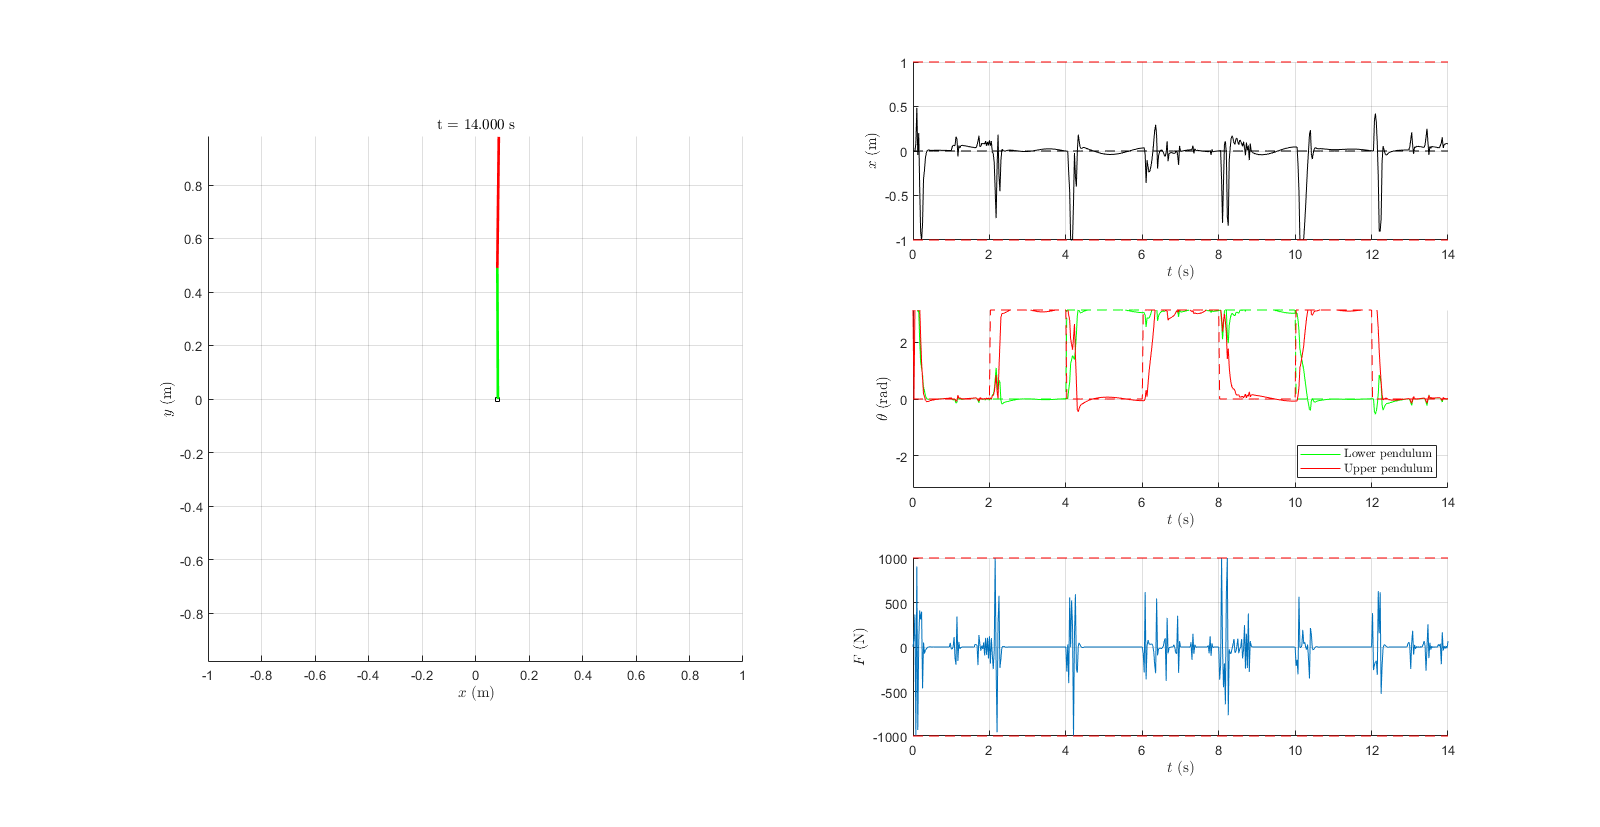

set(0,'DefaultFigureWindowStyle','normal')
set(gcf, 'Position', get(0, 'Screensize'));

for i = 1:length(t)
  set(gcf,'Visible','on')
  set(gcf,'color','white')
  % Update states
  x_cart = xx(1,i);
  t1 = xx(2,i); % theta1
  t2 = xx(3,i); % theta2
  x1 = x_cart + L1*sin(t1);
  x2 = x1 + L2*sin(t2);
  y_cart = 0;
  y1 = y_cart + L1*cos(t1);
  y2 = y1 + L2*cos(t2);
  clf

  % Animation
  subplot(3,2,[1 3 5])
  hold on
  grid on
  %   axis((L1+L2)*[-1 +1 -1 +1])
  ylim((L1+L2)*[-1 +1])
  axis equal
  % Plot the cart
  plot(x_cart,y_cart,'ks','markersize',5)
  % Plot the lower pendulum
  plot([x_cart x1],[y_cart y1],'-g','linewidth',2)
  % Plot the upper pendulum
  plot([x1 x2],[y1 y2],'-r','linewidth',2)
  hold off
  %   legend({'Cart';'Lower pendulum';'Upper pendulum'},...
  %     'interpreter','latex','location','nw')
  grid on
  titulo = sprintf('t = %1.3f s',t(i));
  title(titulo,'interpreter','latex')
  xlabel('$x$ (m)','Interpreter',"latex")
  ylabel('$y$ (m)','Interpreter',"latex")
  xlim([-1,+1])

  % Plot position of the cart
  subplot(3,2,2)
  hold on
  plot(t(1:i),xx(1,1:i),'k')
  plot(t,xs(1,:),'--k')
  plot([0 t(end)],[x_min x_min],'--r')
  plot([0 t(end)],[x_max x_max],'--r')
  hold off
  axis tight
  xlim([0 t(end)])
  grid on
  xlabel('$t$ (s)','Interpreter',"latex")
  ylabel('$x$ (m)','Interpreter',"latex")

  % Plot angle of the pendulums
  subplot(3,2,4)
  hold on
  plot(t(1:i),xx(2,1:i),'g')
  plot(t,xs(2,:),'--g')
  plot(t(1:i),xx(3,1:i),'r')
  plot(t,xs(3,:),'--r')
  hold off
  axis tight
  xlim([0 t(end)])
  ylim(pi*[-1 +1])
  grid on
  xlabel('$t$ (s)','Interpreter',"latex")
  ylabel('$\theta$ (rad)','Interpreter',"latex")
  legend({'Lower pendulum';'';'Upper pendulum';''},...
    'Interpreter',"latex",'Location',"se")

  % Plot control action
  subplot(3,2,6)
  hold on
  plot(t(1:i),u_cl(1:i))
  plot([0 t(end)],[F_min F_min],'--r')
  plot([0 t(end)],[F_max F_max],'--r')
  hold off
  axis tight
  xlim([0 t(end)])
  grid on
  xlabel('$t$ (s)','Interpreter',"latex")
  ylabel('$F$ (N)','Interpreter',"latex")

  pause(.001)
end